# Worksheet 1: Bike Share

#### Due Monday, September 13

Welcome to your first ModSim worksheet! We call them worksheets because, in the olden days (circa 2019), we used to hand them out in the studios, and students would write on them with graphite- or other pigment-based implements. It's now in digital format, but we have tried to preserve the essential elements from times past. These elements include:

- *Work at your own pace.* There are three main parts to this worksheet (plus the reading questions and reflections), and you have three class sessions to complete it. We expect that many students will be able to complete approximately one part per day, with minimal outside work beyond reading the assigned chapters of the Robot Book. That said, you are welcome to work ahead and/or take time after class to finish parts that you don't complete in class, possibly with help from a course assistant (CA). There are also some more challenging optional activities at the end of the worksheet if you'd like to go further.

- *Collaborate with your peers.* As in the past, we will ask you to work in randomly assigned studio groups. You will work with the same group for the duration of the worksheet, sitting together at a table. We encourage you to collaborate closely and discuss each section together. However, each of you will complete and submit an individual copy of the worksheet.

- *Learn by doing.* The worksheets are designed to give you practice with the concepts and skills you will need for the projects in the course. They complement the readings from the Robot Book, as well as the full-class auditorium sessions. If you are able to do the things we ask you to do in the worksheets, you will probably be in good shape for the projects. (And conversely, if you find yourself struggling with the worksheets, you should take the initiative to seek help because we will expect you to be able to do these things in your project work.)

Each worksheet will begin with a set of learning objectives and end with a set of reflection questions to help you deepen your understanding and direct your own learning. Information on assignment submission and assessment can be found on Canvas.

### Learning Objectives

After completing this worksheet, you should be able to:

- Describe the key concepts from Chapters 1-4 (including modeling, simulation, scripts, and debugging), and explain how they relate to each other.

- For a simple model like that of the bike sharing system presented in Chapters 2 and 3, create scripts that (a) update the state of the model for a single time step; (b) simulate the model by running the update script in a loop; and (c) plot the results as a time series (labeling the axes appropriately).

- Modify the implementation of a model to use parameters stored in global variables, and to store the results as vectors.

- Perform a one-parameter sweep of a model, plotting the results on a single graph as a set of time series (labeled appropriately with a legend).

- Reduce the results of a simulation run to a single value (e.g., the final value of a state variable), and perform a two-parameter sweep of a model, plotting the results on a single graph as a set of parameter series (labeled appropriately with a legend).

## 1. Reading Questions

Please read chapters 1–4 of the Robot Book if you haven't already, then answer the following questions.

(Here and in the rest of the worksheet, each question or prompt that asks for a response is numbered. You should replace each "% Your text here" or "% Your code here" placeholder with your response.)

1.1. What is a model? How does modeling relate to simulation?

(Note that the term *simulation* is not defined in the book. [Wikipedia](https://en.wikipedia.org/wiki/Simulation) says, "A simulation is an approximate imitation of ... a process or system that represents its operation over time." That definition is good enough for us!)

**Response:**

A model is a representation of a system in the physical world. Simulations are models that can run repeatedly to illustrate patterns in the data. 

1.2. Describe at least two different ways of modeling the fall of a penny from the top of the Empire State Building. How do your models differ? Which (if any) is more useful for answering the question, "How much would it hurt to get hit by a penny that was dropped off the top of the Empire State Building?"

**Response:**

One way to model the fall of the penny is to develop mathematical models to make predictions about the speed of the penny at different points in time as it falls. A scaled-down, table-top model of the situation could also be used to make predictions about a penny falling off of the top of the Empire State Building. Using a mathematical model would probably be more accurate then a scale model because the scale model would not account for certain conditions that exist in a real world case scenario, such as strong winds, etc., whereas as a mathematical model could account for those things. 

1.3. What is a MATLAB script, and why might you want to write one?

**Response:**

A MATLAB script is a program that you can save which makes it easier to run complex programs. It also prevents you from writing redundant code if you'd like to perform the same sequence of steps on different sets of data. 

1.4. The first three chapters of the book introduce six "theorems of debugging" (there are eight in total; the seventh and eighth are in Chapters 7 and 8, respectively). What does debugging have to do with modeling and simulation? Can you give an example of "debugging" from your previous experience, whether or not in a programming context? 

**Response:**

Debugging is important in making sure that your models work correctly and are accurate. If there are bugs in your code, the model may not run at all. Additionally, if there are logic errors in your code, then the model may be inaccurate, even if your code runs. 

1.5. In Chapter 1 (p. 3), Allen advocates "iterative modeling." In Chapter 3 (pp. 30-31), he advocates "incremental development." What do these approaches have in common? Do you agree with his advice? Why do you think ModSim students often fail to follow it?

**Response: **Incremental development involves writing a piece of a program and then testing it, and only making additions once you've ensured that the rest of your program works correctly. Iterative modelling involves making gradual changes to your model to make sure that it demonstrates your real world system accurately. They both involve making incremental improvements to the item you are working on. I agree with his advice because I've learned through experience that if you try to make multiple changes to code at once then it can make it hard to figure out the piece of your program that isn't working. When you isolate pieces of a larger problem, it's much easier to solve that one piece then trying to debug multiple changes at once. ModSim students may be impatient or may want to get all of their thoughts out at once rather than taking the time to build models gradually. In this way, they fail to execute incremental development. 

## 2. A First-Cut Model

This section of the worksheet closely follows the treatment of the bike share system in the Robot Book. By completing the exercises related to this system in Chapters 2 and 3, you will implement a simple model of bicycle movement between two stations (in Boston and Cambridge), simulate the model for a time period of one month, plot the results, and interpret them.

### Storing and Updating the State of the System

2.1. Work through Chapter 2, Exercise 2 to create a script called `bike_update` that updates the number of bikes in each location (Boston and Cambridge) from one day to the next. Test it here by setting the number of bikes in both locations to 100, then running the update script. How many bikes are in each location after one update step?

**Response:**

b = 100, c = 100;

b = 100

bike_update
b

b = 98

c

c = 102

### Simulating a Month of the Bike Sharing System

2.2. Work through Chapter 3, Exercise 1 to create a script called `bike_loop` that uses a `for` loop to run `bike_update` 30 times. As in the exercise above, start with 100 bikes in each location. Test the script here.

**Response:**

b = 100; 
c = 100;
bike_loop

b = 98

c = 102

b = 96.1600

c = 103.8400

b = 94.4672

c = 105.5328

b = 92.9098

c = 107.0902

b = 91.4770

c = 108.5230

b = 90.1589

c = 109.8411

b = 88.9462

c = 111.0538

b = 87.8305

c = 112.1695

b = 86.8040

c = 113.1960

b = 85.8597

c = 114.1403

b = 84.9909

c = 115.0091

b = 84.1917

c = 115.8083

b = 83.4563

c = 116.5437

b = 82.7798

c = 117.2202

b = 82.1574

c = 117.8426

b = 81.5848

c = 118.4152

b = 81.0581

c = 118.9419

b = 80.5734

c = 119.4266

b = 80.1275

c = 119.8725

b = 79.7173

c = 120.2827

b = 79.3399

c = 120.6601

b = 78.9928

c = 121.0072

b = 78.6733

c = 121.3267

b = 78.3795

c = 121.6205

b = 78.1091

c = 121.8909

b = 77.8604

c = 122.1396

b = 77.6315

c = 122.3685

b = 77.4210

c = 122.5790

b = 77.2273

c = 122.7727

b = 77.0492

c = 122.9508

2.3. What happened? Why?

**Response:**

Boston has 77 bikes and Cambridge has 123 bikes. That occured because Cambridge is recieving more bikes than they gave away, and Boston recieved less bikes than they gave away, leading Boston to have a lower bike count than Cambridge. 

### Plotting the State of the System over Time

2.4. If your `bike_update` script displays the values of `b` and `c`, modify it so that it no longer does so; call the modified script `bike_update2`. Then work through Chapter 3, Exercise 2. Call the modified looping script `bike_loop2`; it should only display a graph as output. Test it here.

**Response:**

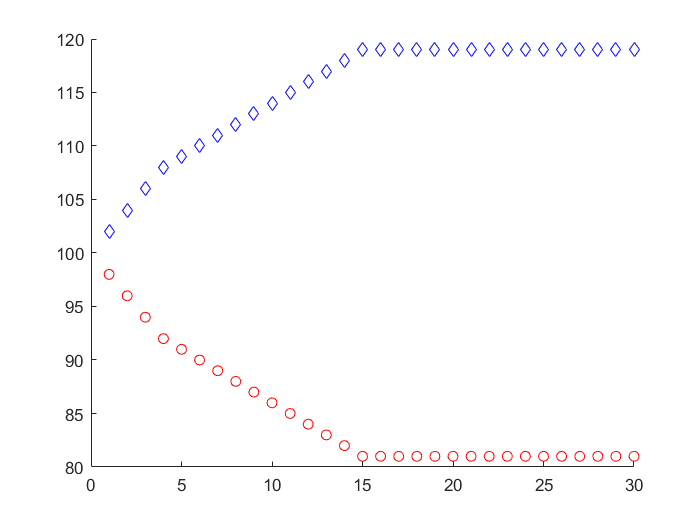

b = 100;
c = 100;
bike_loop2

Congratulations — if you produced a figure that looks like this, you've successfully completed this part!

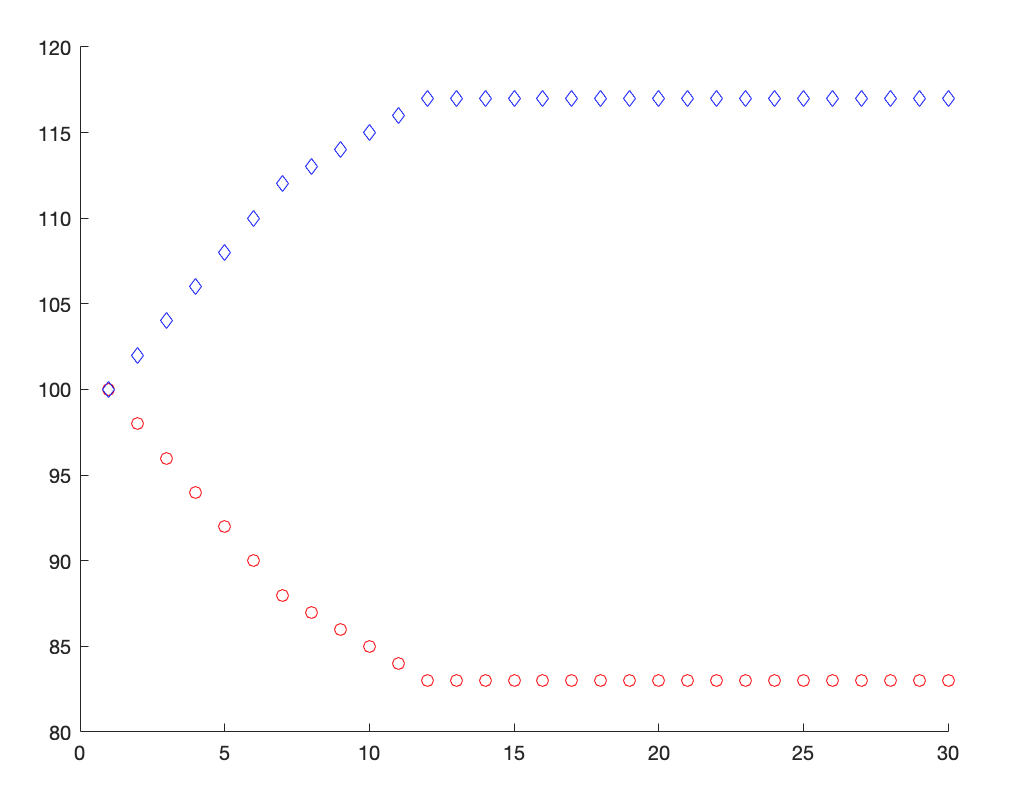

## 3. Sweeping Parameters

In this section of the worksheet, we'll go beyond the treatment of the bike share model in the book to develop some ideas that will play important roles in the rest of the course. In particular, we'll revisit the idea of parameter sweeping that you saw in the in-class notebook on falling pennies, which is important because you'll almost always want to run a simulation multiple times to explore how it behaves for different parameter values.

### Parameters and Results

Before we dive into parameter sweeping, we need to start thinking more clearly about how the parameters and results of our bike share model are stored and manipulated in our scripts.

3.1. What are the parameters of the bike share model? Where are they defined in the scripts you've written so far?

**Response: **The parameters in our bikeshare model are the number of bikes in Boston, the number of bikes in Cambridge, the fraction of bikes going to Boston and the fraction of bikes going to Cambridge. So far, only the number of bikes in Boston and Cambridge are the only parameters defined. 

3.2. What results are generated by a single simulation run of the bike share model? What did we do with them in the scripts you've written so far?

**Response:**

The results generated by a single simulation of the bike share model include the number of bikes in Boston and Cambridge at the end of a given day. Running the simulation moves the values of b and c one day forward. Those points are plotted along a graph with time on the x-axis to illustrate how many bikes there are in each location over 30 days. By doing this, we can discern trends regarding the number of bikes in each location over time. 

3.3. Now create a script called `bike_update3` that uses variables called `b_frac` and `c_frac` to represent the fraction of bikes in Boston and Cambridge (respectively) that move on a given day. Then create `bike_loop3` to call `bike_update3` repeatedly and store the results in vectors called `B` and `C` instead of plotting the state of the system inside the loop. In your response below, call `bike_loop3` and plot the results using one `plot` statement for each vector, replicating the figure you generated at the end of Part 1 above.

**Response:**

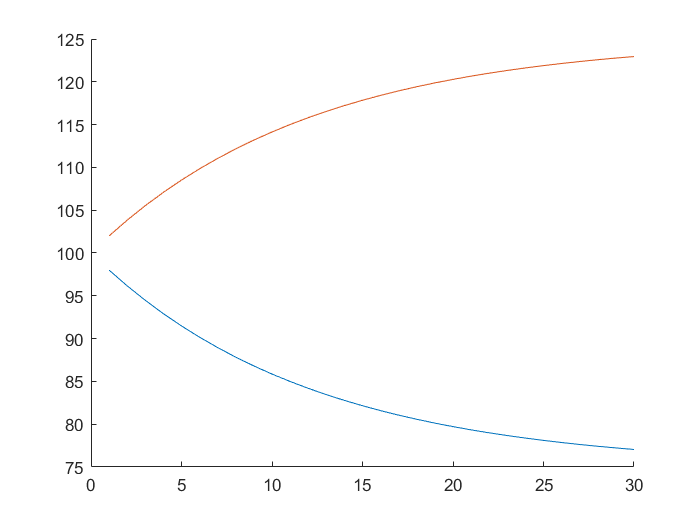

b = 100;
c = 100;
bike_loop3

Now let's add some labels. If your code above generates a plot, this code should label it correctly:

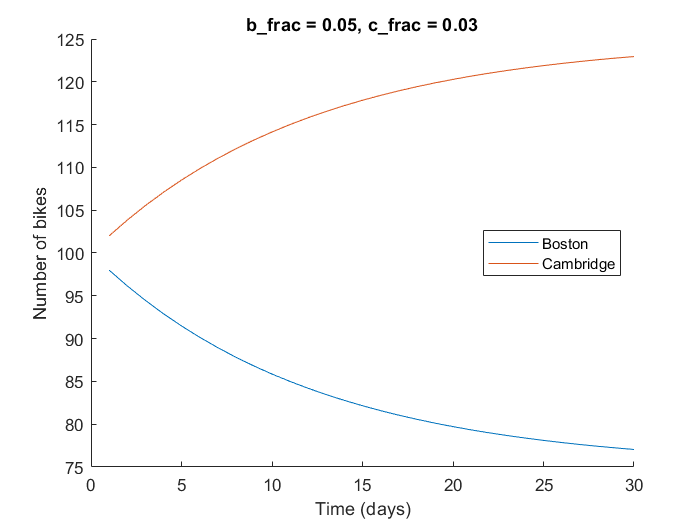

xlabel('Time (days)')
ylabel('Number of bikes')

title(['b\_frac = ', num2str(b_frac), ', c\_frac = ', num2str(c_frac)])
legend('Boston', 'Cambridge', 'Location', 'east');

(You should run the code above, which should generate a nicely labeled plot.)

3.4. Okay, so you've successfully reproduced the same plot you generated in the last part of the worksheet. What's different this time, and why is it better?

**Response:**

This time the lines are solid versus individual points. The shape of the graph adheres to a smoother parabolic shape. This graph is better because it illustrates a more clearly defined pattern and even an equation to model the pattern. 

### Sweeping One Parameter

3.5. Create a script called `bike_sweep_plot` to sweep `b_frac` from 0.01 to 0.07 (in increments of 0.01), and plot the results as a set of time series that are overlaid on the same graph. Hold `c_frac` at 0.03, as in the previous simulations.

*Hint — this code creates a range of values from 1 to 3 in increments of 0.5:*

.01:.07:.01

ans = 0.0100

**Response:**


B =

     []



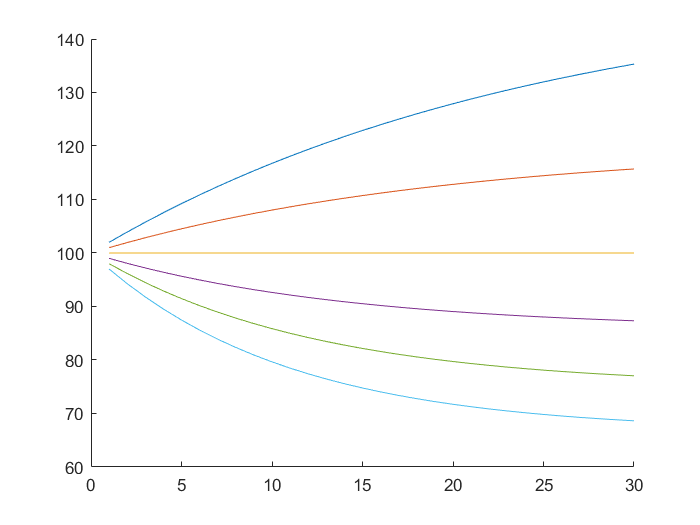

b = 100;
c = 100;
bike_sweep_plot

Once again, let's add some labels. (We are not expecting you to be able to write this code, but you should be able to figure out what it does and modify it appropriately.)

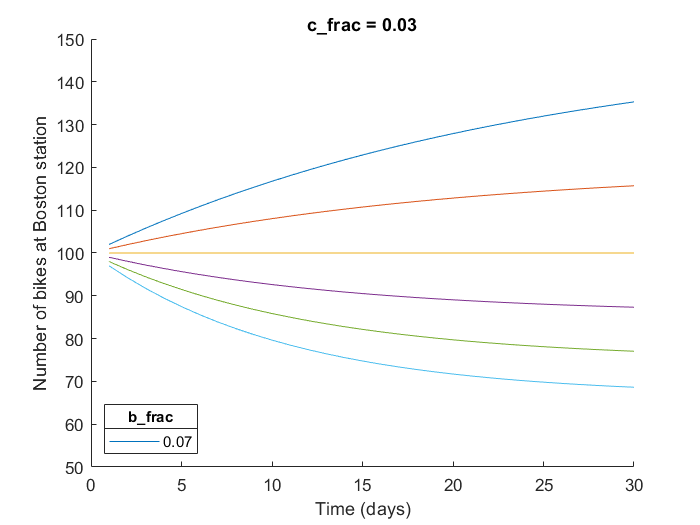

xlabel('Time (days)')
ylabel('Number of bikes at Boston station')
xlim([0 30])      % x-axis limits (specified as a two-element vector)
ylim([50 150])    % y-axis limits (specified as a two-element vector)

title(['c\_frac = ', num2str(c_frac)])

lgd = legend(string(b_frac));  % need to use string(...) to convert
                                     % b_frac_range into a string array
                                     
lgd.Title.String = 'b\_frac';        % need to use \_ to get an underscore
lgd.Location = 'southwest';          % (otherwise _ is interpreted as a subscript)

(Again, please run the code above to generate a nicely labeled plot.)

### Sweeping Two Parameters

3.6. Create a script called `bike_sweep_reduce` to sweep `b_frac` from 0.01 to 0.07, storing the final value of each simulation run in a vector called `B_end`. Run this script for a range of `c_frac` parameter values (also from 0.01 to 0.07), and plot the results as a set of parameter series that are overlaid on the same graph. This time, you create the axis labels and legend!

**Response:**


B_end =

     []


B =

     []



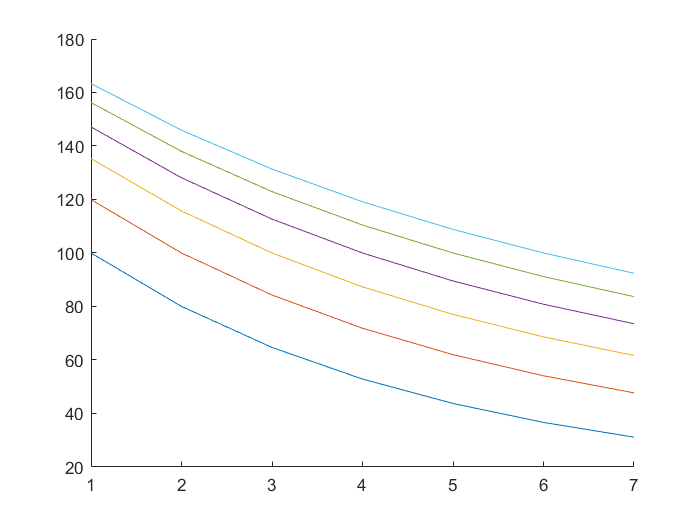

b = 100;
c = 100;
bike_sweep_reduce

## 4. Evaluating and Improving the Model

Whenever we ask you to create a model, we're also going to ask you to interpret and evaluate it. For each of the three projects in the course, you'll also have an opportunity to improve your model based on feedback from your studio instructor and CAs. In this part of the worksheet, we invite you to practice this process in the context of the bike share model you worked with this week.

4.1. What is your assessment of the bike share model? Are there ways in which it is a "good" model of a bike share system, or at least a useful starting point for one? In what ways is it a "bad" model? To what extent do you think these flaws or limitations can be overcome through iterative modeling / incremental development, versus starting again from scratch?

**Response:**

I think that the model accounts for some variability in the fraction of bikes leaving the cities each day, by sweeping the values of b_frac and c_frac. However, these percentages don't make sense in the real world, as the number of bikes taken does not depend on the number of bikes available. Also, based on our model, because we're only reducing by a fraction, the number of bikes won't ever reach 0, which doesn't allow us to accurately answer our question about whether the number of bikes in a given city ever get to 0 or not. 

4.2 Of the many possible ways to improve the bike share model, which would you prioritize for your *next* iteration, and why? In what ways would your changes yield a better model? Do you see any possible risks or downsides?

**Response:**

I would prioritize making more variables in these models, including time and day of week, number of young people in the area, season, whether the area is a tourist destination etc., to more accurately model the number of bikes travelling to and from each location, rather than using a percentage to calculate the number of bikes. This would produce a better model because it would account for lurking variables that aren't factored into this model's calculations. Possible risks and downsides include increased complexity, which could lead to innaccurate or illegible plots. Also, there are still lurking variables that influence the number of bikes transfered between each location beyond what is listed, including the number of other stops in the bike share system, and bikes that break down or get stolen, etc. Additionally, these variables are hard to predict, meaning that the model may still be inaccurate. 

## 5. Reflection Questions

The purpose of this final section is to give you an opportunity to reflect on your experience in completing the worksheet. This information may be helpful for your studio instructor, but it is mainly intended to be helpful to you.

5.1. What was the most challenging part of this worksheet for you? Did you get stuck at any point along the way? If so, what strategies did you employ to get unstuck, and how did they work?

**Response:**

The most challenging part of this worksheet for me was 3.5 because I didn't understand what belonged on each axis.  After I spoke to CAs, upperclassmen, and my peers, I was able to realize what the question was asking for and realized that time belonged on the x-axis rather than b_frac. Specifically, I spoke to students in the library when I was working on the worksheet there and I spoke to group members and went to office hours. I now have a comprehensive understanding of the modules in this worksheet because of the extensive time I spent working collaboratively and independently.

5.2. How did the studio group experience work for you? To what extent were you able to seek and receive help from your peers? What are some things you can do next week to make these interactions more effective for your learning? What are some things the instructors or CAs can do?

**Response:**

The group experience went very well in that everyone was friendly and did their part to help others in the group. Although my group was quiet, we communicated very well and helped each other when necessary. We also tried to keep everyone on pace with the assignment so that we all finished on time. Next time, I'll do even more check ins with my peers to help everyone learn the material. One thing instructors and CAs can do is schedule additional office hours. Sometimes one office hour has a lot of first years and only one CA to help. It might be helpful to have more CAs at office hours in case there are a lot of people so that everyone can get help in a reasonable amount of time.  